clear
clc
a = csvread('thick2rgb.csv');
x = a(:,1);
ry = a(:,2);
gy = a(:,3);
by = a(:,4);

model = @(b, x) b(1)+b(2)*exp(-b(3)*x)+2*(b(1)*b(2))^0.5*exp(-b(4)*x).*cos(4*pi*x/600*1.4);
%构造问题对象
problem = createOptimProblem('lsqcurvefit', ...%优化方法
'objective', model, ...%目标函数
'xdata', x, 'ydata', ry, ...%值
'x0',ones(1,4),...%初始试探值
'lb', [0 0 0 0 ],...%参数下限
'ub', [100 100 1 1]) %参数上限

problem = 包含以下字段的 struct :
    objective: @(b,x)b(1)+b(2)*exp(-b(3)*x)+2*(b(1)*b(2))^0.5*exp(-b(4)*x).*cos(4*pi*x/600*1.4)
           x0: [1 1 1 1]
        xdata: [18×1 double]
        ydata: [18×1 double]
           lb: [0 0 0 0]
           ub: [100 100 1 1]
       solver: 'lsqcurvefit'
      options: [1×1 optim.options.Lsqcurvefit]


ms = MultiStart;%随机多次优化对象
ms.Display = 'iter';
rng default
[~,fval,exitflag,output,solutions] = run(ms, problem, 100)%尝试50次全局优化

    Run       Local       Local      Local    Local   First-order
   Index     exitflag      f(x)     # iter   F-count   optimality
       1         3    1.468e+05         9        50     0.0001014
       2         3    7.926e+04        17        90         5.199
       3         3    7.926e+04        17        90         5.461
       4         3    7.926e+04        15        80         7.391
       5         3    7.926e+04        16        85         10.73
       6         3    7.926e+04        17        90         9.109
       7         3    7.926e+04        18        95         9.664
       8         3    7.926e+04        18        95         8.706
       9         3    7.926e+04        22       115         8.747
      10         3    7.926e+04        12        65          7.79
      11         3    7.926e+04        14        75         108.5
      12         3    7.926e+04        18        95         6.874
      13         3    7.926e+04        20       105         5.888
      14  

fval = 7.9257e+04

exitflag = 1

output = 包含以下字段的 struct :
                funcCount: 8640
         localSolverTotal: 100
       localSolverSuccess: 100
    localSolverIncomplete: 0
    localSolverNoSolution: 0
                  message: 'MultiStart completed the runs from all start points.↵↵All 100 local solver runs converged with a positive local solver exit flag.'


solutions =   1×41 GlobalOptimSolution 数组 - 属性:

    X
    Fval
    Exitflag
    Output
    X0


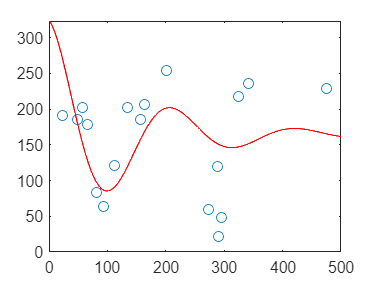

plot(x,ry,'o'), hold on
xx = 1:500;
cc2=model(solutions(1,1).X,xx);
plot(xx,cc2,'r-'),hold off

solutions(1,1).X%最优值的解

ans =   100.0000   64.1387    0.0000    0.0069


solutions(1,1).Fval%最优值的残差

ans = 7.9257e+04

rexp = @(i1, i2, j1, j2, x) i1+i2*exp(-j1*x)+2*(i1*i2)^0.5*exp(-j2*x).*cos(4*pi*x/600*1.4);
roption = fitoptions(rexp,'lower',[0 0 0 0],'upper',[100 100 1 1]);
rp = fit(x,ry,rexp,roption);

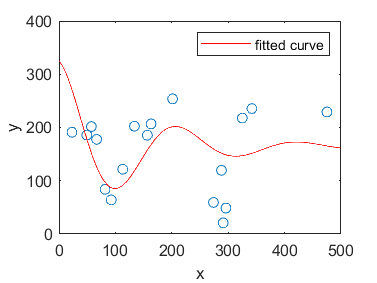

figure
plot(x,ry,'o')
hold on
plot(rp)
hold off

gexp = @(i1, i2, j1, j2, x) i1+i2*exp(-j1*x)+2*(i1*i2)^0.5*exp(-j2*x).*cos(4*pi*x/560*1.4)

gexp = 包含以下值的 function_handle :
    @(i1,i2,j1,j2,x)i1+i2*exp(-j1*x)+2*(i1*i2)^0.5*exp(-j2*x).*cos(4*pi*x/560*1.4)


goption = fitoptions(gexp,'lower',[0 0 0 0]);
gp = fit(x,gy,gexp,goption);

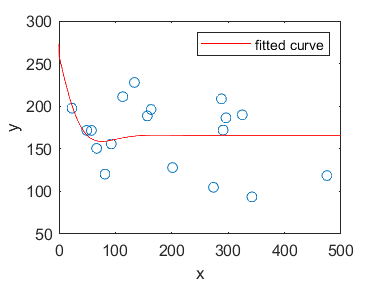

figure
plot(x,gy,'o')
hold on
plot(gp)
hold off

bexp = @(i1, i2, j1, j2, x) i1+i2*exp(-j1*x)+2*(i1*i2)^0.5*exp(-j2*x).*(4*pi*x/470*1.4)

bexp = 包含以下值的 function_handle :
    @(i1,i2,j1,j2,x)i1+i2*exp(-j1*x)+2*(i1*i2)^0.5*exp(-j2*x).*(4*pi*x/470*1.4)


boption = fitoptions(bexp,'lower',[0 0 0 0]);
bp = fit(x,by,bexp,boption);

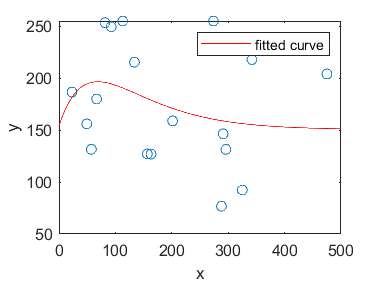

figure
plot(x,by,'o')
hold on
plot(bp)
hold off

% b = imread('test.png');
% siz = size(b);
% matrix = ones(siz(1),siz(2));

% rgbmatrix = zeros(3,500,'double');
% for i = 1:500
%     rgbmatrix(1,i) = rp(i);
%     rgbmatrix(2,i) = gp(i);
%     rgbmatrix(3,i) = bp(i);
% end

% save('rm.mat',"rgbmatrix")